# Sort Classes by Precision or Recall

Create a confusion matrix chart and sort the classes of the chart according to the class-wise true positive rate (recall) or the class-wise positive predictive value (precision).

Load and inspect the `arrhythmia` data set.

load arrhythmia
isLabels = unique(Y);
nLabels = numel(isLabels)

nLabels = 13

tabulate(categorical(Y))

  Value    Count   Percent
      1      245     54.20%
      2       44      9.73%
      3       15      3.32%
      4       15      3.32%
      5       13      2.88%
      6       25      5.53%
      7        3      0.66%
      8        2      0.44%
      9        9      1.99%
     10       50     11.06%
     14        4      0.88%
     15        5      1.11%
     16       22      4.87%


The data contains 16 distinct labels that describe various degrees of arrhythmia, but the response (`Y`) includes only 13 distinct labels.

Train a classification tree and predict the resubstitution response of the tree.

Mdl = fitctree(X,Y);
predictedY = resubPredict(Mdl);

Create a confusion matrix chart from the true labels `Y` and the predicted labels `predictedY`. Specify `'RowSummary'` as `'row-normalized'` to display the true positive rates and false positive rates in the row summary. Also, specify `'ColumnSummary'` as `'column-normalized'` to display the positive predictive values and false discovery rates in the column summary.

fig = figure;
cm = confusionchart(Y,predictedY,'RowSummary','row-normalized','ColumnSummary','column-normalized');

Resize the container of the confusion chart so percentages appear in the row summary.

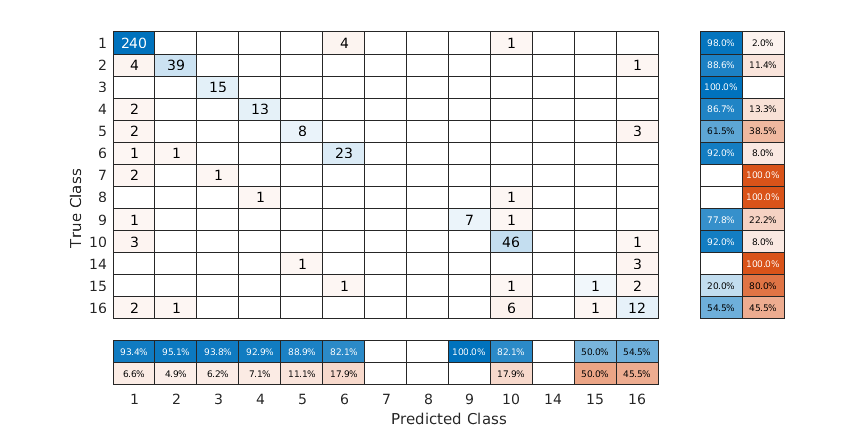

fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

To sort the confusion matrix according to the true positive rate, normalize the cell values across each row by setting the `Normalization` property to `'row-normalized'` and then use `sortClasses`. After sorting, reset the `Normalization` property back to `'absolute'` to display the total number of observations in each cell.

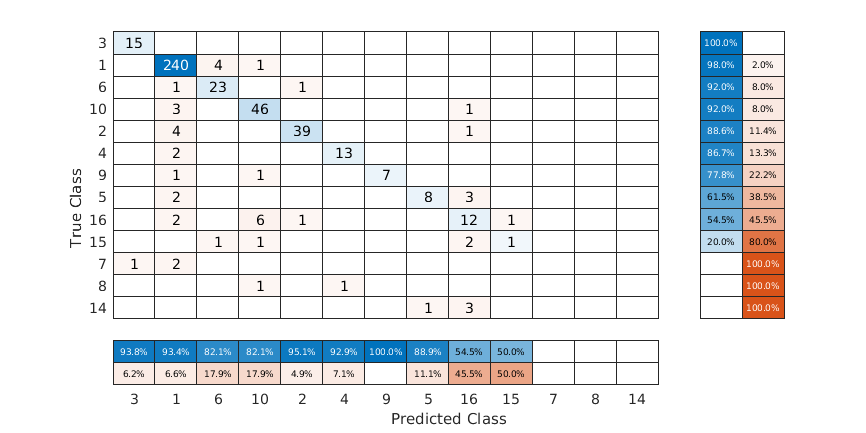

cm.Normalization = 'row-normalized'; 
sortClasses(cm,'descending-diagonal')
cm.Normalization = 'absolute'; 

To sort the confusion matrix according to the positive predictive value, normalize the cell values across each column by setting the `Normalization` property to `'column-normalized'` and then use `sortClasses`. After sorting, reset the `Normalization` property back to `'absolute'` to display the total number of observations in each cell.

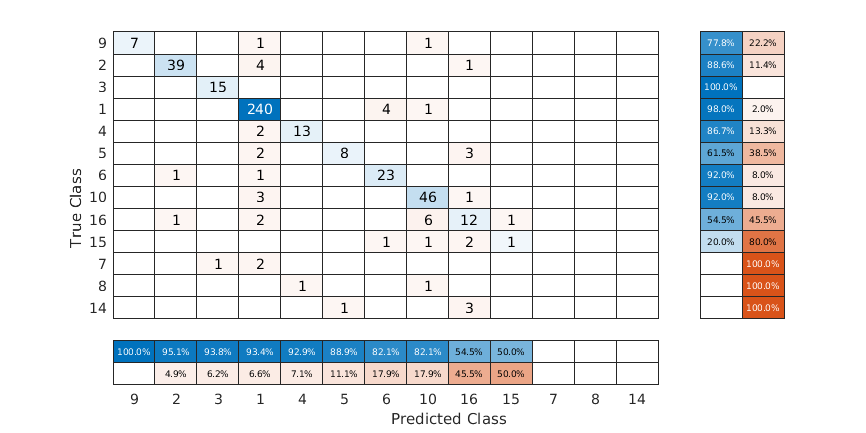

cm.Normalization = 'column-normalized';
sortClasses(cm,'descending-diagonal')
cm.Normalization = 'absolute';  

*Copyright 2018 The MathWorks, Inc.*